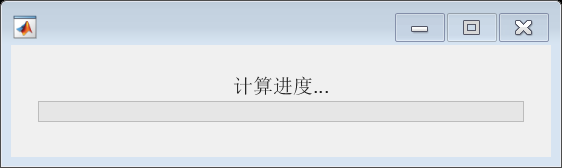

D = parallel.pool.DataQueue;
h = waitbar(0, '计算进度...');

h.UserData = 0; % 初始化计数器
% 初始化GPU
if gpuDeviceCount > 0
    disp('GPU is available');
    useGPU = true;
else
    error('No GPU available');
end

GPU is available


batchSize=1000;

%% 获得正确杆长参数组合
% 遍历所有组合
k=1;
L1_array=linspace(50, 250, 20*k+1);   % L1
L2_array=linspace(50, 250, 20*k+1);   % L2
L3_array=linspace(50, 250, 20*k+1);   % L3
L4_array=linspace(50, 250, 20*k+1);   % L4
L5_array=linspace(145, 175, 3*k+1);   % L5
L6_array=linspace(100, 160, 7);   % L6
param_combinations = [];
size(param_combinations)

ans =      0     0


tic;
num_L1 = length(L1_array);
temp_combinations = cell(num_L1, 1);
deadline=0.8;
parfor i1 = 1:num_L1
    L1 = L1_array(i1);
    local_combinations = [];
    
    % L2筛选：L2 > L1
    valid_L2 = L2_array(L2_array > L1); 
    
    for i2 = 1:length(valid_L2)% 转置为列向量
        L2=valid_L2(i2);
        % L4筛选：L4 < L1
        valid_L4 = L4_array(L4_array < L1); 
        
        for i4 = 1:length(valid_L4)
            % L3筛选：L3 > L4
            L4=valid_L4(i4);
            valid_L3 = L3_array(L3_array > L4); 
            
            for i3 = 1:length(valid_L3)
                L3=valid_L3(i3);
                product1 = L1 * L2;
                product2 = L3 * L4;
                
                % 检查第一个等式：(L1*L2)/(L3*L4) ∈ [0.95,1.05]
                if (product1/product2 < (1.0-deadline)) || (product1/product2 > (1.0+deadline))
                    continue; 
                end
                
                % % 计算L5平方范围[[7]]
                % L5_sq_lower = max(product1/(1.0+deadline), product2/(1.0+deadline));
                % L5_sq_upper = min(product1/(1.0-deadline), product2/(1.0-deadline));
                % 
                % if L5_sq_lower > L5_sq_upper
                %     continue;
                % end
                % 
                % % L5筛选：同时满足平方范围和L5-L4>55
                % valid_L5 = L5_array( (L5_array.^2 >= L5_sq_lower) & ...
                %                     (L5_array.^2 <= L5_sq_upper) & ...
                %                     (L5_array - L4 > 55) );
                valid_L5 = L5_array(L5_array - L4 > 55 );
                % 最终验证三个等式误差范围
                for i5 = 1:length(valid_L5)
                    L5=valid_L5(i5);
                    ratio2 = product1 / (L5^2);
                    ratio3 = product2 / (L5^2);

                    if abs(ratio2-1)<=deadline && abs(ratio3-1)<=deadline
                    local_combinations = [local_combinations; L1, L2, L3, L4, L5];
                    end
                end
            end
        end
    end
    if ~isempty(local_combinations)
        temp_combinations{i1} = local_combinations;
    end
end
new_param_combinations = vertcat(temp_combinations{:});  % 合并所有结果
param_combinations=repmat(new_param_combinations,length(L6_array),1);
param_combinations(:,6)=repelem(L6_array,1,size(new_param_combinations,1))

param_combinations =     60    80    90    50   145   100
    60    80   100    50   145   100
    60    80   110    50   145   100
    60    80   120    50   145   100
    60    80   130    50   145   100
    60    80   140    50   145   100
    60    80   150    50   145   100
    60    80   160    50   145   100
    60    80   170    50   145   100
    60    80   180    50   145   100


toc;

历时 0.193208 秒。



disp(size(param_combinations));

      143052           6



total_combinations=length(param_combinations);

sector = struct(...
    'r_min', 100,...   % 内半径
    'r_max', 350,...  % 外半径
    'theta_min', deg2rad(-140),...  % 起始角度（弧度）
    'theta_max', deg2rad(-40)...  % 终止角度（弧度）
);

% 预处理：预先计算角度边界的三角函数值以加速计算
sector.sin_theta_min = sin(sector.theta_min);
sector.cos_theta_min = cos(sector.theta_min);
sector.sin_theta_max = sin(sector.theta_max);
sector.cos_theta_max = cos(sector.theta_max);
% 计算扇区面积
sector_area = (sector.r_max^2 - sector.r_min^2)*(sector.theta_max-sector.theta_min)/2;
% %样例测试，小范围
% [F_x, F_y] = calculateTrajectory(150, 170, 270, 100, 170,100, 0,sector);
% figure;
% scatter(F_x, F_y, 5, 'filled');
% hold on;
% 
% % Plot the circles
% 
% for r = 100:50:350
%     theta = linspace(sector.theta_min, sector.theta_max, 1000); % 足够多的点使曲线平滑
%     x = r * cos(theta);
%     y = r * sin(theta);
%     plot(x, y, 'Color', [0.5 0.5 0.5], 'LineStyle', '--'); % 灰色虚线
% end
% 
% % Add the transparent fan ring
% theta_fan = linspace(sector.theta_min,sector.theta_max, 100); % Angular range from 1.25pi to 1.75pi
% r_inner = 100; % Inner radius
% r_outer = 350; % Outer radius
% 
% % Coordinates for the inner and outer edges of the fan ring
% x_inner = r_inner * cos(theta_fan);
% y_inner = r_inner * sin(theta_fan);
% x_outer = r_outer * cos(theta_fan);
% y_outer = r_outer * sin(theta_fan);
% 
% % Create the filled sector (fan ring) by connecting the inner and outer edges
% fill([0, x_outer, fliplr(x_inner)], [0, y_outer, fliplr(y_inner)], 'y', 'FaceAlpha', 0.4, 'EdgeColor', 'none'); 
% hold off;
% xlabel('X (mm)');
% ylabel('Y (mm)');
% title('五连杆末端点云轨迹');
% xlim([-200, 200]);
% 
% ylim([-350, -100]);
% axis equal;
% grid on;
% scores(1)=evaluateSectorOptimized(F_x,F_y,0,sector_area);

% 设置监听器
afterEach(D, @(~) updateWaitbar(h, total_combinations));
% 主计算循环
is_valid=true(1,total_combinations);
scores=single(zeros(total_combinations,1));
parfor i = 1:total_combinations  % 使用parfor并行计算
    % 获取当前参数组合
    current_params = param_combinations(i, :);
    [L1, L2, L3, L4, L5,L6] = deal(current_params(1), current_params(2),...
                               current_params(3), current_params(4),...
                               current_params(5),current_params(6));
    try
        [F_x, F_y] = calculateTrajectory(L1, L2, L3, L4, L5,L6, useGPU,sector);
        scores(i)=evaluateSectorOptimized(F_x,F_y,0,sector_area)
    catch ME
        is_valid(i)=false;
        warning('函数计算出错');
    end
    if mod(i, batchSize) == 0
        send(D, batchSize); % 发送批量大小作为增量
    end
end

警告: 检测到并删除了重复的数据点。
> 位置：LiveEditorEvaluationHelperE1305203211>evaluateSectorOptimized (第 301 行)
位置: parallel_function>make_general_channel/channel_general (第 837 行)
位置: 

close(h); % 关闭进度条
delete(h);
% 保存完整结果
good_combinations=param_combinations;
good_combinations(:,7)=scores(:);
good_combinations=good_combinations(is_valid,:);
valid_score=scores>0.8;
good_combinations=good_combinations(valid_score,:);
[~, sort_idx] = sort(good_combinations(:, end), 'descend');
top100_params=good_combinations(sort_idx(1:100),:);
save('data/all_results.mat','good_combinations','sort_idx','top100_params');
clear;
toc;

历时 411.947164 秒。


function [F_x_final, F_y_final] = calculateTrajectory(L1, L2, L3, L4, L5,L6, useGPU,sector)
% 固定参数
n = 120;  % 适当降低采样精度以节省计算资源
A = [-L5/2, 0]; E = [L5/2, 0]; % 固定点
% 生成角度网格
theta1 = linspace(0, 2*pi, n);
theta4 = linspace(0, 2*pi, n);
theta1=single(theta1);
theta4=single(theta4);
if useGPU
    theta1 = gpuArray(theta1);
    theta4 = gpuArray(theta4);
end

% 后续计算与原代码相同，此处省略...
% 创建网格并向量化
[theta1_grid, theta4_grid] = meshgrid(theta1, theta4);
theta1_vec = theta1_grid(:);
theta4_vec = theta4_grid(:);

% 计算B点和D点坐标（向量化计算）
Bx = A(1) + L1 * cos(theta1_vec);
By = A(2) + L1 * sin(theta1_vec);
Dx = E(1) + L4 * cos(theta4_vec);
Dy = E(2) + L4 * sin(theta4_vec);

% 计算连杆方程参数
delta_x = Dx - Bx;
delta_y = Dy - By;

% 计算判别式（完全向量化）
A0 = 2 * L2 * delta_x;
B0 = 2 * L2 * delta_y;
C0 = L2^2 + delta_x.^2 + delta_y.^2 - L3^2;
discriminant = A0.^2 + B0.^2 - C0.^2;

A1 = 2 * L3 * (-delta_x);
B1 = 2 * L3 * (-delta_y);
C1 = L3^2 + delta_x.^2 + delta_y.^2 - L2^2;
discriminant1 = A1.^2 + B1.^2 - C1.^2;

% 初步筛选有效索引
valid_idx = discriminant >= 0 & discriminant1 >= 0;
if ~any(valid_idx)
    error('No valid configurations found');
end
% 提取有效角度组合
theta1_valid = theta1_vec(valid_idx);
theta4_valid = theta4_vec(valid_idx);
Bx_valid = Bx(valid_idx);
By_valid = By(valid_idx);
Dx_valid = Dx(valid_idx);
Dy_valid = Dy(valid_idx);

% 计算theta2（只计算有效点）
sqrt_disc = sqrt(discriminant(valid_idx));
theta2 = 2 * atan2((B0(valid_idx) + sqrt_disc), (A0(valid_idx) + C0(valid_idx)));

% 计算C点坐标
Cx = Bx_valid + L2 * cos(theta2);
Cy = By_valid + L2 * sin(theta2);

% 几何约束条件判断（向量化）
cha1 = (Dx_valid - Cx) .* (E(2) - Cy) - (Dy_valid - Cy) .* (E(1) - Cx);
cha2 = (Bx_valid - A(1)) .* (Cy - A(2)) - (By_valid - A(2)) .* (Cx - A(1));

% 处理除零情况
delta_DCx = Dx_valid - Cx;
non_zero = delta_DCx ~= 0;
flag1 = zeros(size(delta_DCx), 'like', delta_DCx);
flag1(non_zero) = (Dy_valid(non_zero) - Cy(non_zero)) ./ delta_DCx(non_zero);

% 避免条件判断中的除零错误
flag2 = A(2) > (flag1 .* (A(1) - Cx) + Cy);

% 最终有效条件
condition_above = Cy > By_valid; 

% 修改有效点判断逻辑
final_valid = cha1 < 0 | cha2 > 0 | (flag2 & (flag1 < 0)); 
valid_points = (~final_valid) & condition_above; 

% 计算最终坐标
F_x = Cx(valid_points) + (L6/L2)*(Cx(valid_points) - Bx_valid(valid_points));
F_y = Cy(valid_points) + (L6/L2)*(Cy(valid_points) - By_valid(valid_points));

% Y坐标筛选
y_valid = F_y > 0;
F_x = F_x(y_valid);
F_y = -F_y(y_valid);

% 极径条件（使用平方避免开方运算）
r_sq = F_x.^2 + F_y.^2;
valid_r = (r_sq >= sector.r_min^2) & (r_sq <= sector.r_max^2);

% 角度条件（通过叉积判断方向）
cross_min = F_x * sector.sin_theta_min - F_y * sector.cos_theta_min;
cross_max = F_x * sector.sin_theta_max - F_y * sector.cos_theta_max;
valid_theta = (cross_min <= 0) & (cross_max >= 0);

% % 综合掩膜
valid_mask = valid_r & valid_theta;
% 获取区域内的点
Fx_in = F_x(valid_mask);
Fy_in = F_y(valid_mask);

% 返回最终坐标
F_x_final = gather(Fx_in);
F_y_final = gather(Fy_in);
end

function score = evaluateSectorOptimized(Fx_in, Fy_in,useGPU,area)
    % 传输数据到GPU（如启用）
    if useGPU
        % Fx_in = gpuArray(F_x);
        % Fy_in = gpuArray(F_y);
    end
    % 改进的面积计算
if numel(Fx_in) < 3
    area_in = 0;
    
else
    % 极角
    shp = alphaShape(double(Fx_in), double(Fy_in));  % 50 这个值可以调整

    % shp.Alpha=criticalAlpha(shp,'one-region');%目标单连通区域，自动设置最优半径
    shp.Alpha=min(criticalAlpha(shp,'one-region'),10);
    [~,by] = boundaryFacets(shp);  % 获取边界点
    Fx_in=by(:,1);
    Fy_in=by(:,2);


    % figure;
    % scatter(Fx_in, Fy_in, 5, 'filled');
    % xlabel('X (mm)');
    % ylabel('Y (mm)');
    % title('五连杆末端点云轨迹');
    % xlim([-200, 200]);
    % ylim([-350, -100]);
    % axis equal;
    % grid on;


    center_x = mean(Fx_in);
    center_y = mean(Fy_in);
    % 计算相对质心的极角
    [~, idx] = sort(atan2(Fy_in - center_y, Fx_in - center_x));
    sorted_x = Fx_in(idx);
    sorted_y = Fy_in(idx);                
    % 多边形面积公式
    x_shift = circshift(sorted_x, -1);
    y_shift = circshift(sorted_y, -1);
    area_in = 0.5 * abs(sum(sorted_x.*y_shift - x_shift.*sorted_y));
end
    % 得分公式：（面积比 - 惩罚项）
    score_ratio = area_in / area;
    % score = max(0, score_ratio - penalty); % 确保得分非负
    score = max(0, score_ratio); % 确保得分非负

    score = gather(score);
end
function updateWaitbar(h, total)
batchSize=1000;
h.UserData = h.UserData + batchSize;
percentComplete = h.UserData / total * 100; % 计算完成百分比
% if abs(percentComplete-30)<0.01 || abs(percentComplete-60)<0.01
waitbar(percentComplete / 100, h, sprintf('完成 %.2f%%', percentComplete)); % 更新进度条并显示百分比
end